Let us start by defining a system of multivariate polynomial equations in the standard monomial basis:

eqs = cell(2,1); % eqs is the cell representation of a system.
eqs{1} = [1 2 0; 1 1 1; -2 0 0]; 
eqs{2} = [1 0 2; 1 1 1; -2 0 0]; 
sys = systemstruct(eqs); % sys is the system/struct representation of a system.
disp(sys)

  systemstruct with properties:

               coef: {2×1 cell}
               supp: {2×1 cell}
                  n: 2
                  s: 2
                 di: {2×1 cell}
               dmax: 2
               nnze: {2×1 cell}
              basis: 'monomial'
                 ma: []
                 mb: []
    macaulaylabtime: []
        citationkey: []
               type: 'system'



We can retrieve the properties of the system of multivariate polynomial equations from the system:

disp(sys.supp)

    {3×2 double}
    {3×2 double}



help probleminfo

  probleminfo retrieves the information about the problem.
 
    [s,n,di,dmax,nnze,k,l] = probleminfo(problem) returns the basic
    properties of the problem.
 
    Input argument:
        problem [struct]: system of multivariate polynomial equations
        or multiparameter eigenvalue problem.
 
    Output arguments:
        s [int]: number of (matrix) equations.
        n [int]: number of variables.
        di [cell(s,1)]: total degree of every (matrix)
        equation.
        dmax [int]: maximum total degree of the problem.
        nnze [cell(s,1)]: number of non-zero coefficients of every
        (matrix) equation.
        k [int]: number of rows of the coefficient matrices.
        l [int]: number of columns of the coefficient matrices.



[s, n, di, dmax, nnze] = probleminfo(sys) % retrieves information from the system representation.

s = 2

n = 2

di = 2×1 cell array
    {[2]}
    {[2]}


dmax = 2

nnze = 2×1 cell array
    {[3]}
    {[3]}


We can, of course, also define a system of multivariate polynomial equations in the Chebyshev polynomial basis:

cheb = randomsystem(2,2,2); % a dense system with random coefficients.
cheb.basis = 'chebyshev'; % simply adds information about the basis to the system representation.
disp(cheb) % note that the display changes to the correct basis!

  systemstruct with properties:

               coef: {2×1 cell}
               supp: {2×1 cell}
                  n: 2
                  s: 2
                 di: {2×1 cell}
               dmax: 2
               nnze: {2×1 cell}
              basis: 'chebyshev'
                 ma: []
                 mb: []
    macaulaylabtime: []
        citationkey: []
               type: 'system'



It easy to solve a system out-of-the-box

macaulaylab(sys)

ans =    -1.0000   -1.0000
    1.0000    1.0000


Some new bounds on the number of solutions:

bezout(dreesen1)

ans = 4

kushnirenko(dreesen1)

ans = 4

bkk(dreesen1)

ans = 4

Now, let us solve some systems step-by-step:

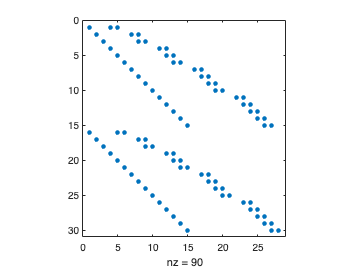

M = macaulay(sys,6);
spy(M)

[X,output] = macaulaylab(sys); % default solver with dend = degree of Macaulay bound.
[X,output] = macaulaylab(sys,10); % default solver with dend = 10.
options = struct; options.verbose = true; % options are always set as a struct.
help macaulaylab % you can find a full list of all the options/outputs in the documentation!

  macaulaylab solves a system of multivariate polynomial equations or
  (rectangular) multiparameter eigenvalue problem via the (block)
  Macaulay matrix.
 
    [X] = macaulaylab(problem) solves the problem with default options. 
    The final degree of the function is then set equal to 30.
    
    [___] = macaulaylab(___,dend) uses a user-specified final degree.
    It is recommended to set this argument!
 
    [___,output] = macaulaylab(___,options) uses user-specified options
    and stores the output arguments.
 
    Input arguments:
        problem [struct]: system of multivariate polynomial equations
        or (rectangular) multiparameter eigenvalue problem.
        dend [int - optional/recommended]: final degree (default = 30).
        options [struct - optional]: user-specified options.
            - options.null [boolean]: selects the null space based
              approach, instead of column space based app

[X,output] = macaulaylab(sys,10,options); % verbose solver with dend = 10.

                                MacaulayLab                                 
___________________________________________________________________________ 
 
The system has 2 equations in 2 variables (maximum total degree is 2). 
 
The selected polynomial basis is the monomial basis 
 
The solver tackles the system via the null space of the Macaulay matrix: 
  *  Building a basis matrix of the null space (sparse - block row-wise) 

 	 | degree 	 | nullity 	 | increase 	 |gap zone 	 | 
	 |---------------------------------------------------------------| 
	 | 2 	 	 | 4 	 	 | x 	 	 | NaN 	 	 | 
	 | 3 	 	 | 4 	 	 | 0 	 	 | 0 	 	 | 
	 | 4 	 	 | 4 	 	 | 0 	 	 | 1 	 	 | 

	 required degree = 4 
	 gap degree = 2 
	 gap zone size = 1 
	 total number of solutions = 4 
	 number of affine solutions = 2 
	 required time (enlarge) = 0.0104 seconds 
	 required time (check) = 0.0007 seconds 
  *  Performing a column compression: 
	 from 4 to 2 solutions 
	 required time 


options = struct; options.verbose = true; options.blocked = false;
[X,output] = macaulaylab(sys,10,options); % verbose solver with row-wise shifts.

                                MacaulayLab                                 
___________________________________________________________________________ 
 
The system has 2 equations in 2 variables (maximum total degree is 2). 
 
The selected polynomial basis is the monomial basis 
 
The solver tackles the system via the null space of the Macaulay matrix: 
  *  Building a basis matrix of the null space (sparse - row-wise) 

 	 | degree 	 | nullity 	 | increase 	 |gap zone 	 | 
	 |---------------------------------------------------------------| 
	 | 2 	 	 | 4 	 	 | x 	 	 | NaN 	 	 | 
	 | 3 	 	 | 4 	 	 | 0 	 	 | 0 	 	 | 
	 | 4 	 	 | 4 	 	 | 0 	 	 | 1 	 	 | 

	 required degree = 4 
	 gap degree = 2 
	 gap zone size = 1 
	 total number of solutions = 4 
	 number of affine solutions = 2 
	 required time (enlarge) = 0.0058 seconds 
	 required time (check) = 0.0082 seconds 
  *  Performing a column compression: 
	 from 4 to 2 solutions 
	 required time = 0.00

options = struct; options.verbose = true; options.algorithm = 'column';
[X,output] = macaulaylab(sys,10,options); % verbose solver that works in the column space.

                                MacaulayLab                                 
___________________________________________________________________________ 
 
The system has 2 equations in 2 variables (maximum total degree is 2). 
 
The selected polynomial basis is the monomial basis 
 
The solver tackles the system via the null space of the Macaulay matrix: 
  *  Building a basis matrix of the null space (sparse - block row-wise) 

 	 | degree 	 | nullity 	 | increase 	 |gap zone 	 | 
	 |---------------------------------------------------------------| 
	 | 2 	 	 | 4 	 	 | x 	 	 | NaN 	 	 | 
	 | 3 	 	 | 4 	 	 | 0 	 	 | 0 	 	 | 
	 | 4 	 	 | 4 	 	 | 0 	 	 | 1 	 	 | 

	 required degree = 4 
	 gap degree = 2 
	 gap zone size = 1 
	 total number of solutions = 4 
	 number of affine solutions = 2 
	 required time (enlarge) = 0.0018 seconds 
	 required time (check) = 0.0005 seconds 
  *  Performing a column compression: 
	 from 4 to 2 solutions 
	 required time 

Good, everything is basis independent... I will prove it!

M = macaulay(sys,6,@basischeb); % the given function handle contains the shift definition.
spy(M)
value(cheb.coef{1}, cheb.supp{1}, [1 1], @evalcheb) % evaluate first polynomial in (1,1). 

If you use `option.basis`, then you set two function handles (which you can also supply to the solver yourself):

- `options.mult = @basischeb` to set the shift definition in the given polynomial basis.

- `options.eval = @evalcheb` to define how to evaluate a polynomial in the given polynomial basis.

options = struct; options.verbose = true; options.basis = 'chebyshev'; 
[X,output] = macaulaylab(randomsystem(2,2,2),10,options); % verbose solver in the Chebyshev basis.

What if the system is a positive-dimensional solution set at infinity?

type dreesen10

function [system] = dreesen10() 
    % DREESEN10 contains a system of multivariate polynomial equations. 
    % 
    %   [system] = DREESEN10() returns the system of multivariate 
    %   polynomial equations. 
    %
    %   Note: This system of multivariate polynomial equations has a
    %   positive-dimensional solution set at infinity.

    % MacaulayLab (2022) - Christof Vermeersch. 

    eqs = cell(4,1); 
    eqs{1} = [1 1 0 0 0; 1 0 1 0 0; -1 0 0 0 0]; 
    eqs{2} = [1 1 0 1 0; 1 0 1 0 1]; 
    eqs{3} = [1 1 0 2 0; 1 0 1 0 2; -0.6666666667 0 0 0 0]; 
    eqs{4} = [1 1 0 3 0; 1 0 1 0 3]; 

    system = systemstruct(eqs); 
end


What if the system is over-determined?

type overdet1

function [system] = overdet1() 
    eqs = cell(8,1); 
    eqs{1} = [1 1 1 1 1; -1 1 1 0 1; -1 1 0 1 1; 1 1 0 0 1; -1 0 1 1 1; ...
        1 0 1 0 1; 1 0 0 1 1; -1 0 0 0 1; -1 1 1 1 0; 1 1 1 0 0; 1 1 0 1 0; ...
        - 1 1 0 0 0; 1 0 1 1 0; -1 0 1 0 0; -1 0 0 1 0; 1 0 0 0 0]; 
    eqs{2} = [1 1 1 0 0; -1 1 0 0 0; -1 0 1 0 0; 1 0 0 0 0]; 
    eqs{3} = [-1 0 1 1 1; 1 0 1 0 1; 1 0 0 1 1; -1 0 0 0 1; 1 0 1 1 0; -1 0 1 0 0; ...
        -1 0 0 1 0; 1 0 0 0 0]; 
    eqs{4} = [-1 1 0 1 1; 1 1 0 0 1; 1 0 0 1 1; -1 0 0 0 1; 1 1 0 1 0; -1 1 0 0 0; ...
        -1 0 0 1 0; 1 0 0 0 0]; 
    eqs{5} = [1 2 0 0 0; -1 1 0 0 0];
    eqs{6} = [1 0 2 0 0; -1 0 1 0 0];
    eqs{7} = [1 0 0 2 0; -1 0 0 1 0];
    eqs{8} = [1 0 0 0 2; -1 0 0 0 1];
    
    system = systemstruct(eqs); 
end


Also works in the block Macaulay matrix:

mep = randommep(2,2,4,3); % generates an MEP with random coefficient matrices.
disp(mep)
hkp(mep) % computes the Hochstenbach-Kosir-Plestenjak bound on the number of solutions.
options = struct; options.verbose = true;
[X,output] = macaulaylab(mep,15,options); % verbose solver with dend = 15.